# L4 - Ex 1-  Ariadna Cortés Danés

clear all
format long

### (a)

Com canvia el nombre de condició d’aquesta matriu quan l’ordre creix? Presenta un estudi per  5≤n≤30

n_cond = [];
n = 5:30;
for nn = n
    
    % Creem la matriu
    A = zeros(nn);
    A(1,1:2) = [-1 1];
    A(end,nn-1:nn) = [1 -1];
    for ii = 2:(nn-1)
        A(ii,ii-1:ii+1) = [1 4 1];
    end
    
    % Creem el vector de termes independents b
    b = zeros(nn,1);
    for ii = 2:nn-1
        b(ii,1) = 6;
    end 
    
    n_cond = [n_cond cond(A)];
end

table(n',n_cond', 'VariableNames',["n", "nombre de condicionament"])

ans = 26×2 table
    n     nombre de condicionament
    __    ________________________

     5        4.60623153673433    
     6        4.72381376131961    
     7        4.79982526168265    
     8        4.84939391068889    
     9        4.88288625871089    
    10        4.90641208987857    
    11        4.92352531544844    
    12         4.9363499161352    
    13        4.94620423880861    
    14          4.953938074775    
    15        4.96011823313093    
    16        4.96513426627912    
    17        4.96926097146143    
    18        4.97269665577608    
    19        4.97558731613285    
    20        4.97804235538285    


### (b) 

Resoleu el sistema lineal Ax=b per eliminació gaussiana sense pivotament.

% octave Matlab pg 148 
t_gem = [];
for nn = n
    
    % Creem la matriu
    A = zeros(nn);
    A(1,1:2) = [-1 1];
    A(end,nn-1:nn) = [1 -1];
    for ii = 2:(nn-1)
        A(ii,ii-1:ii+1) = [1 4 1];
    end
    
    % Creem el vector de termes independents b
    b = zeros(nn,1);
    for ii = 2:nn-1
        b(ii,1) = 6;
    end 
    
   %% Resolem per GEM sense pivotament
    tic
    
    for k = 1:nn-1
        for i = k+1:nn
        A(i,k) = A(i,k)/A(k,k);
        j = [k+1:nn]; A(i,j) = A(i,j) - A(i,k)*A(k,j);
        end
    end

    t_gem = [t_gem toc];
end


### (c) 

Resoleu el sistema lineal Ax=b fent ús de la funció de Matlab® DECOMPOSITION i   \ . Escolliu, si cal, la millor opció de decomposition per la vostra matriu.

t_dA = [];
for nn = n
    
    % Creem la matriu
    A = zeros(nn);
    A(1,1:2) = [-1 1];
    A(end,nn-1:nn) = [1 -1];
    for ii = 2:(nn-1)
        A(ii,ii-1:ii+1) = [1 4 1];
    end
    
    % Creem el vector de termes independents b
    b = zeros(nn,1);
    for ii = 2:nn-1
        b(ii,1) = 6;
    end 
    
   % Resolem per descomposicio
    tic
    dA = decomposition(A);
    x = dA\b;
    t_dA = [t_dA toc];
end

### (d) 

Resoleu el sistema lineal Ax=b  pel mètode de Gauss-Seidel.

t_gs = [];
for nn = n
    
    % Creem la matriu
    A = zeros(nn);
    A(1,1:2) = [-1 1];
    A(end,nn-1:nn) = [1 -1];
    for ii = 2:(nn-1)
        A(ii,ii-1:ii+1) = [1 4 1];
    end
    
    % Creem el vector de termes independents b
    b = zeros(nn,1);
    for ii = 2:nn-1
        b(ii,1) = 6;
    end 
    
   % Resolem per Gauss-Seidel
    tic
    D = diag(diag(A));
    d = diag(1./diag(A)); %inversa de la matriu diagonal
    L = tril(A,-1);
    U = triu(A,1);
    
    Bg = -inv(L+D)*U;
    cg = inv(L+D)*b;
    
    r = [1];
    k = 0;
    x = zeros(size(b));

    while (r(end) > 10e-8)  %tolerancia 10e-8
        x = Bg*x + cg;
        r =[r norm(b - A*x,1)];
        k = k+1;
    end
    t_gs = [t_gs toc];
end


fprintf("Nombre d'iteracions: %d", k)

Nombre d'iteracions: 14

### (e) 

Consulteu la documentació de Matlab®: Measure the Performance of Your Code, i Techniques to Improve Performance. Afegiu el còmput del temps en els tres tòpics treballats. Presenteu els resultats en taules.  

temps = table(n',t_gem',t_dA',t_gs','VariableNames',["n" "Temps GEM sense piv." "Temps amb decomposition" "Temps Gauss-Seidel"])

temps = 26×4 table
    n     Temps GEM sense piv.    Temps amb decomposition    Temps Gauss-Seidel
    __    ____________________    _______________________    __________________

     5         0.0048908                 0.1264371               0.0220519     
     6         0.0031418                 0.0065565               0.0078103     
     7         0.0019484                 0.0064046               0.0049166     
     8         0.0002466                 0.0069447               0.0005438     
     9         0.0007276                 0.0303313               0.0059715     
    10         0.0002436                 0.0008966               0.0004504     
    11         0.0002917                 0.0010437               0.0001301     
    12         0.0003534                 0.0004064               0.0001569     
    13         0.0004049                 0.0

### (f) 

Comenteu els avantatges i els inconvenients dels tres mètodes i l’evolució dels resultats quan $$n$$ es fa gran.

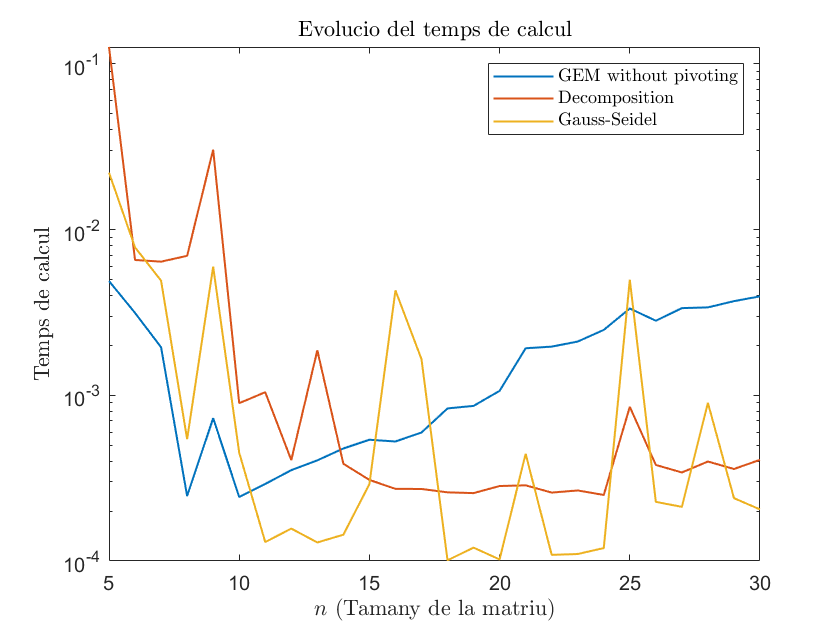

% Per a veure l'evolució dels temps quan n es fa gran, els representarem en
% una mateixa gràfica
figure(1)
semilogy(n,t_gem, 'LineWidth',1)
hold on;
semilogy(n,t_dA, 'LineWidth',1)
semilogy(n,t_gs, 'LineWidth',1)
title("Evolucio del temps de calcul", "Interpreter","latex")
xlabel("$n$ (Tamany de la matriu)", "Interpreter","latex")
ylabel("Temps de calcul", "Interpreter","latex")
legend("GEM without pivoting", "Decomposition", "Gauss-Seidel", "Interpreter","latex")
hold off;

Podem veure que, per a ns relativament petites, el mètode de Gauss sense pivotament obté els millors resultats, 

sent el mes ràpid dels tres mètodes. A mida que n creix, el temps d'aquest mètode també creix, mentre que el temps

dels altres dos mètodes decreix. Podem concloure que per a ns grans, el mètode de Gauss-Seidel o de descomposició

presenta millors results que el mètode de Gauss sense pivotament.